Casadi solver test

Scenario: coasting with vx = 10m/s, with torque actuation cost function.

Cost function: sum((obj.nu).^2) + sum((obj.tau/10).^2)

Control constraint: [-5, 5] (rad/s),    [-1000,1000] (Nm)

Initial constraint: exact

Path constraint: n/a

Terminal constraint: n/a

Solver initialization: all zero except vx = 10, omega_f = omega_r = 30, px = linspace(0,max)

LESSON LEARNED:

making the tire model more smooth (differentiable) really makes the difference.

addpath('C:\Program Files\casadi-windows-matlabR2016a-v3.5.5');
import casadi.*
% MPC subproblem settings
clear
T = 0.5;    % seconds
N = 15;     % number of control intervals

OCP = vehOCP(N,T);
OCP.opti.subject_to();  % an empty call to Opti.subject_to() will clear all the constraints,just a demo
OCP.build_basics();
OCP.actuation_objective();

Actuation objective added!


OCP.add_control_bounds(); % use default bounds
v_xb0 = 10; v_yb0 = 0; px0 = 0; py0 = 0; r0 = 0; psi0 = 0; omega_f0 = 30; omega_r0 = 30; delta0 = 0;
OCP.add_initial_conditions(v_xb0,v_yb0,px0,py0,r0,psi0,omega_f0,omega_r0,delta0); % driving straight
OCP.add_ego_centers();
OCP.set_solver_init(10, 0, 0, 0, 0, 0, 30, 30, 0);  % vx,vy,px,py,r,psi,wf,wr,delta
px0_array = linspace(0,T*v_xb0, N+1);
OCP.opti.set_initial(OCP.px,px0_array); % initialize px with a linearly increasing array

% demonstration: two racing equality conditions will confuse the solver! So
% no feasible solution will be found as a result.
% OCP.opti.subject_to(OCP.vx(1)==1.1*v_xb0);
% OCP.opti.subject_to(OCP.vx(1)==v_xb0);
% OCP.opti.subject_to(OCP.vx(1) <= 10000);
% OCP.opti.subject_to(OCP.vx(1)==v_xb0 + 1e0);


Observation: when we add a duplicate subject_to() call to bound the initial condition, it causes the solver to fail in finding a feasible solution that was originally there. There are some deeper misunderstanding on how the subject_to() function works in implementing the constraints.



solver_opts = struct('max_iter',500);
plugin_opts = struct('print_time',true);
% solver_opts = struct('max_iter',1000,'hessian_approximation','limited-memory','tol',1e-3);
try
    sol = OCP.solve(plugin_opts,solver_opts);
catch
    disp("Solution Not Found.");
end

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     1209
Number of nonzeros in inequality constraint Jacobian.:       30
Number of nonzeros in Lagrangian Hessian.............:      675

Total number of variables............................:      174
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      144
Total number of inequality constraints...............:       30
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:       30
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

if ~exist('sol','var')
    foundSol = false
    sol = OCP.opti.debug;
else
    foundSol = true
end

foundSol = logical
   1


If the solver has a solution, we can visualize the states, intermediate variables, controls.

If the solver failed, we can still use opti.debug.value() to investigate the values of variables.

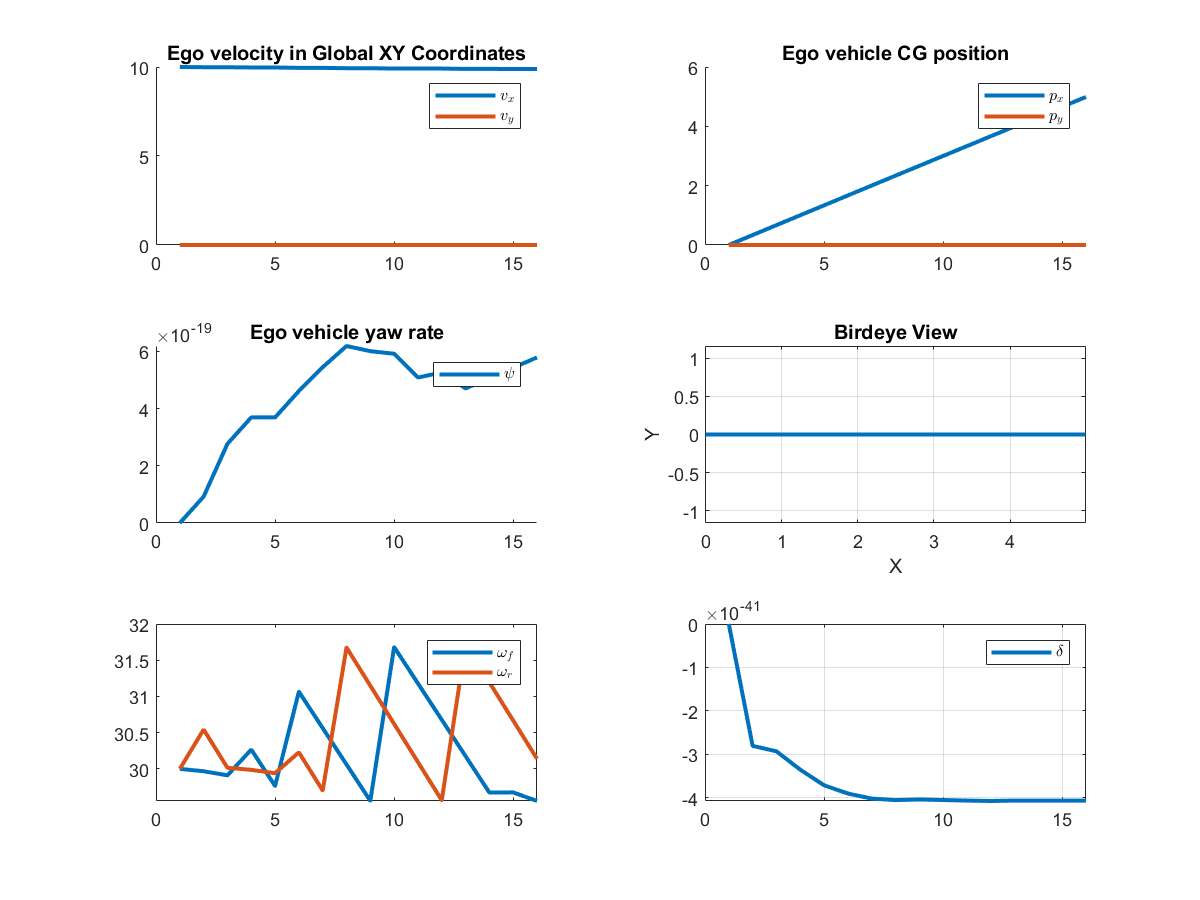

% if solutin is found, set foundSol = true. Otherwise set foundSol = false, and 
% the debug results will be used instead.
% [cost, cost_vx, cost_vy, cost_py] = pp.calculate_cost(OCP,sol,foundSol)
pp.basic_plots_dugoff(OCP,sol);

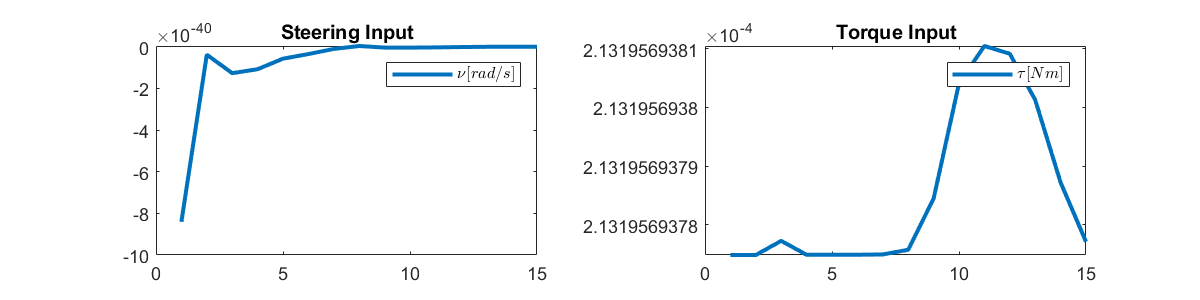

pp.controls_plot_dugoff(OCP,sol)

% pp.debug_plot(OCP,sol,foundSol)

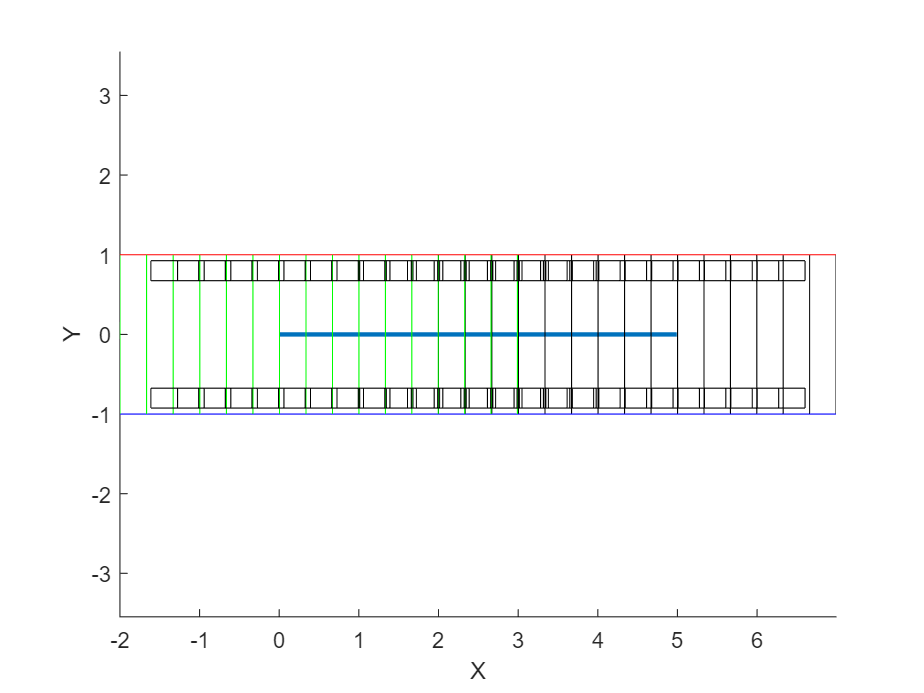

pp.rectangle_overlap(OCP,sol);

Use the 3-circle representation:

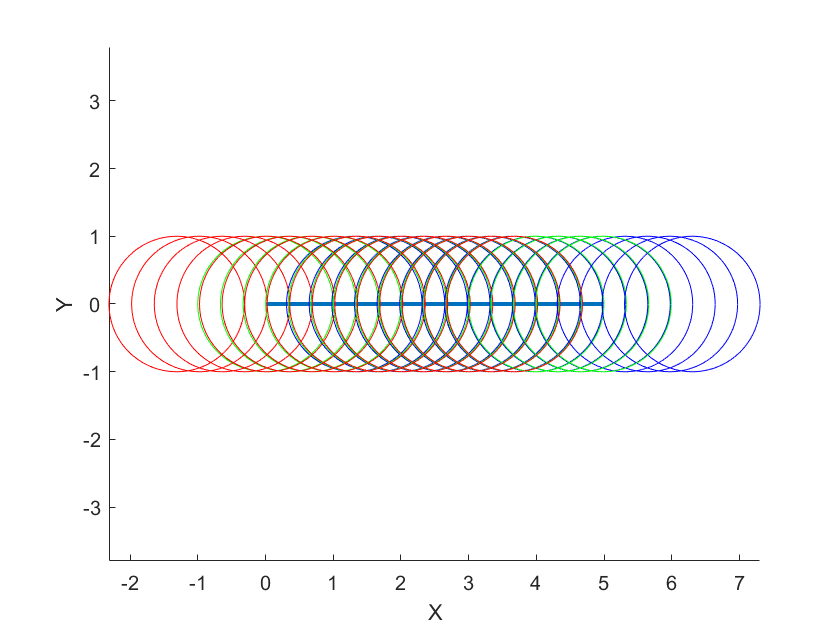

pp.circles_overlap(OCP,sol);

Check constraint violations (cv)

cv_control_bounds = dbg.control_bounds_violation(sol, OCP, 5, 1000)

cv_control_bounds = 0

cv_initial_constraints = dbg.initial_constraints_violation(sol, OCP, v_xb0,v_yb0,px0,py0,r0,psi0,omega_f0,omega_r0,delta0)

cv_initial_constraints = 0

% cv_path_constraints = dbg.path_constraints_violation(sol,OCP,px0,py0,5,2)
% cv_collision_violation = dbg.collision_constraints_violation(sol,OCP)
cv_dynamic_constraints = dbg.dynamic_constraints_violation(sol, OCP)

cv_dynamic_constraints = 1.1455e-12

Animation

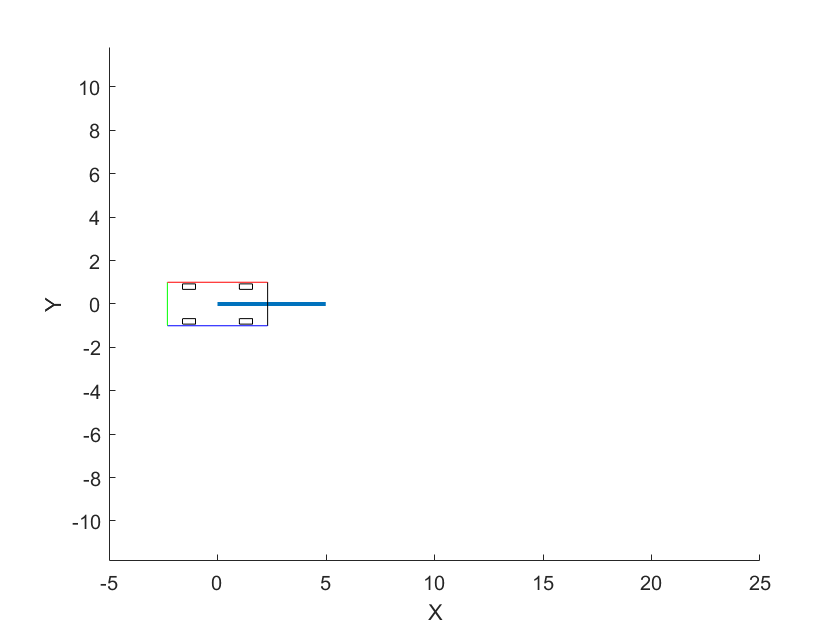

Video saved as: C:\github\vehicle-MPC-CasADi-MATLAB\src\video.avi


pp.make_video_rectangles(OCP,sol,'video',foundSol);